# Create a phase pattern to control the beam location

In this live script we create a phase pattern to control the location of the beam using a linear grating and a spherical lens.  This example includes sliders to control the generated phase pattern and the corresponding position of the beam.

## Setup some parameters for the simulation

% First step is usually to add the toolbox to the path
addpath('../../');

% Then we define the SLM (pattern) size and centre
sz = [512, 512];
centre = sz ./ 2;

## Setup the incident beam

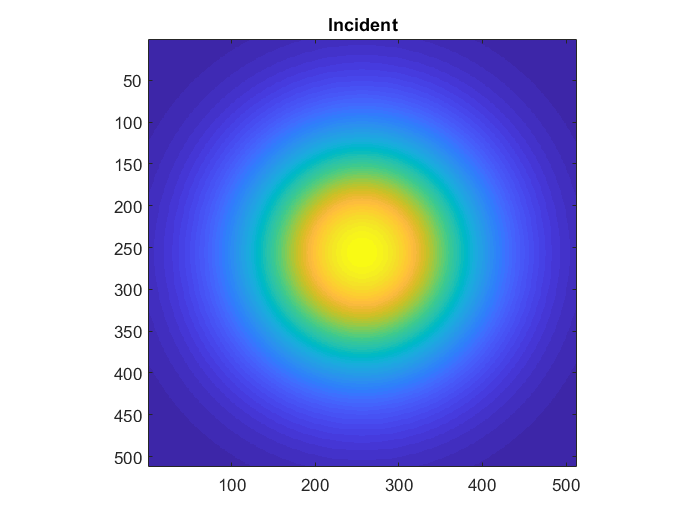

type = 'gaussian';
switch type
    case 'gaussian'
        beam_width = 101;
        incident = otslm.simple.gaussian(sz, beam_width);
    case 'plane'
        incident = ones(sz);
    otherwise
        error('Unknown beam type')
end

imagesc(incident); axis image; title('Incident');

## Generate the phase function to control the beam

First lets setup some sliders to control the patterns

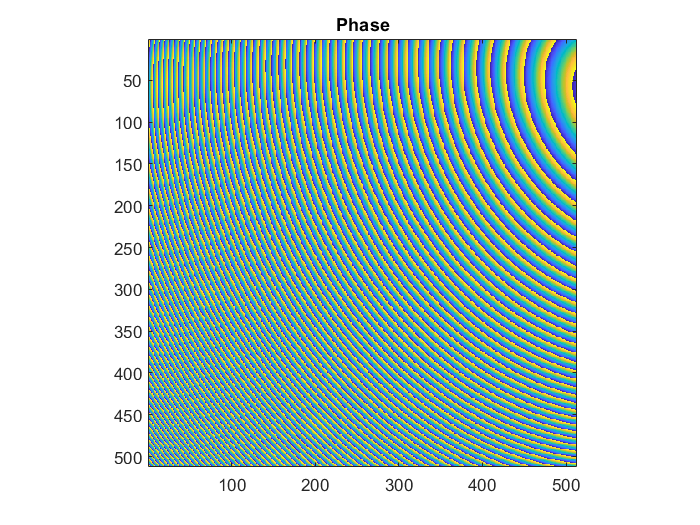

x_inv_spacing =50;
y_inv_spacing =-30;
z_offset = -60;

lin = otslm.simple.linear(sz, sz./[x_inv_spacing, y_inv_spacing], ...
    'centre', centre);
sph = otslm.simple.spherical(sz, min(sz), ...
    'scale', z_offset, 'centre', centre);

pattern = lin + sph;
pattern = otslm.tools.finalize(pattern);
imagesc(pattern); axis image; title('Phase');

## Visualise the far-field

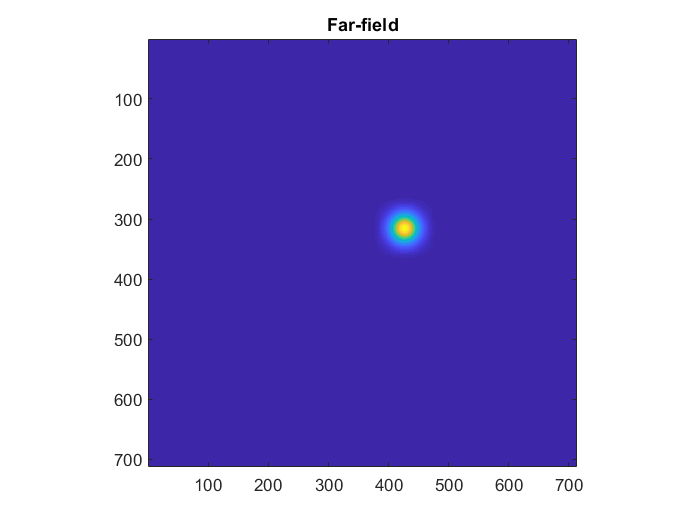

farfield = abs(otslm.tools.visualise(pattern, 'incident', incident));
imagesc(farfield); axis image; title('Far-field');

## About

This example live script is part of OTSLM.  Written by Isaac Lenton.  For further details see [https://github.com/ilent2/otslm](https://github.com/ilent2/otslm)